battCellData = readtable("mitCellData\VTC6_1_60_34.73_10_20181103T115614Z.csv");

battCellData(:,{'Temp1', 'Temp2', 'Temp3'}) = [];
battCellData.Time_s_ = battCellData.Time_s_(:,1) - battCellData.Time_s_(1,1);
battCellData.Power = battCellData.Volts .* battCellData.Amps;
battCellData.JoulesUsedPerStep = [0; diff(battCellData.Time_s_)] .* battCellData.Power;
battCellData.CumulativeJoules = cumsum(battCellData.JoulesUsedPerStep)

battCellData = 9887×6 table
    Time_s_     Volts        Amps         Power       JoulesUsedPerStep    CumulativeJoules
    ________    ______    __________    __________    _________________    ________________

           0    4.1897    0.00010681    0.00044751               0                   0     
    0.096806    4.1897       0.94258        3.9492          0.3823              0.3823     
     0.18941    4.1897       0.94258        3.9492         0.36573             0.74803     
     0.28981    4.1897       0.94258        3.9492         0.39647              1.1445     
     0.38978    4.0042        8.6738        34.731           3.472              4.6165     
     0.49105    4.0042        8.6738        34.731          3.5173              8.1338     
     0.59618    4.0042        8

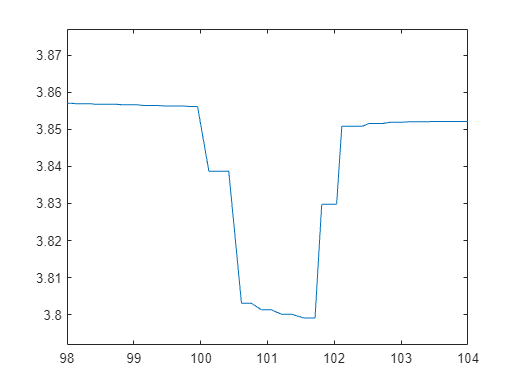


plot(battCellData.Time_s_,battCellData.Volts)

xlim([98.0 104])
ylim([3.7918 3.8771])


%plot(downSampledBatt.Time_s_, downSampledBatt.Volts)
%title( 'Volts vs Time')
%vtcCell10Data = table(138.*downSampledBatt.Volts, 690.*downSampledBatt.CumulativeJoules,'VariableNames',{'Volts','Energy Used'})
%exportName = 'vtc6Lookup.csv';
%writetable(vtcCell10Data,exportName)

